# Лабораторна Робота #3 ЦОС

## студента: Красницького Микити

Початкові умови згідно варіанту

close all
clear all
fs = 1000;
f1 = 90;
f2 = 200;
d1 = 3;
d2 = 20;
j = sqrt(-1);
f = 1:1:2*f2;
w = 2*pi*f;

Дані з розрахункової

w1 = 581;
w2 = 1453;
f1 = w1/(2*pi);
f2 = w2/(2*pi);
l1 = 0.707;
l2 = 0.064;
n = 3;

Згідно розрахункової роботи для 9го Варіанту запишу аналоговий прототип

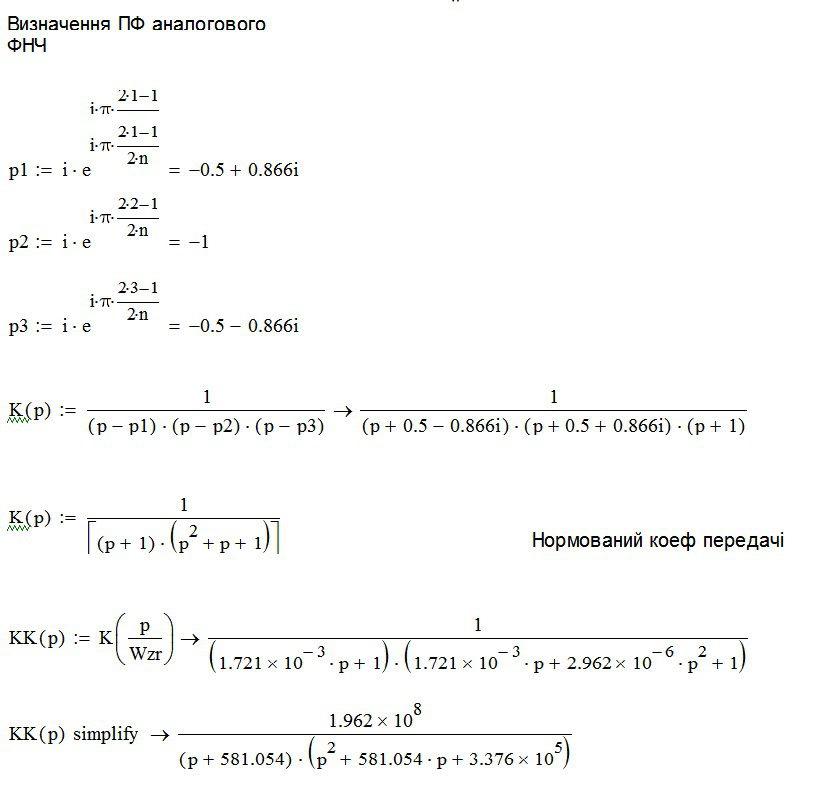

K(f) = 1./sqrt(1 + (f/f1).^(2*n));
subplot(2,2,1);
plot(f, K(f));
hold on
plot([f1, f2], [l1 l2], '*');
grid on;
axis([0 1.2*f2 0 1]);
title('Аналоговий прототип');
ylabel('K(f)');
xlabel('f, Гц');

запишу ПФ, побудую нуль-полюсну діаграмму

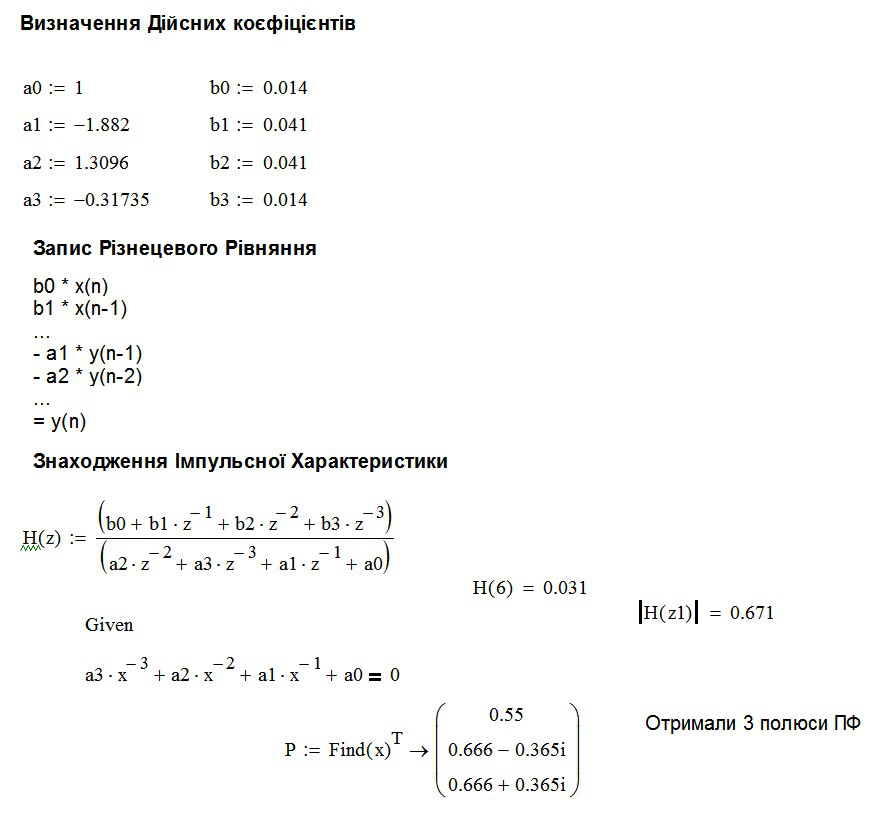

% 
% %АЧХ аналового фільтру
% f = 0 : 1 : 150;
% K = (31006276.6)./(197392.*f*2*pi*j-628.3.*(f*2*pi).^2+(j*2*pi.*f).^3+31006276.6);
% subplot(2,2,1);
% plot(f, abs(K));
% grid on;
% xlabel('f, Гц');
% ylabel('K');
% 
% % Розрахунок прототипу

Коефіцієнти чисельника

b0 = 0.014;
b1 = 0.041;
b2 = 0.041;
b3 = 0.014;

Коефіцієнти знаменника

a1 = -1.882;
a2 = 1.3096;
a3 = -0.317;

Розрахунок ПФ ЦФ

z = exp(j.*((f./fs)*2*pi));
H1 = (b0+b1.*z.^(-1)+b2.*z.^(-2)+b3.*z.^(-3))./(1+a1.*z.^(-1)+a2.*z.^(-2)+a3.*z.^(-3));
subplot(2,2,2);
plot(f,abs(H1));
grid on;
axis([0 1.2*f2 0 1]);
xlabel('f, Гц');
ylabel('H');
title('АЧХ ЦФ');

Знаходжу нулі та полюси як корені чисельницка та знаменника

null = roots([b0 b1 b2 b3]);
poll = roots([1 a1 a2 a3]);
subplot(2,2,3);
zplane(null, poll);
title('Нулі та полюси');

Знаходжу імпульсну характеристику

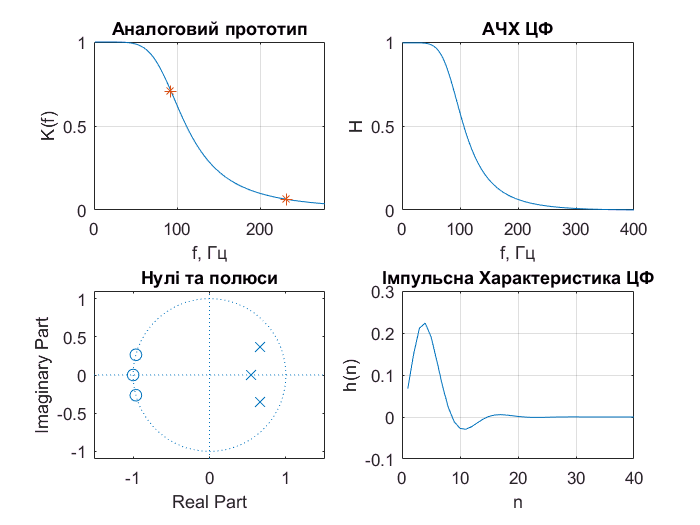

z1 = poll(1);
A1 = (b0+b1.*z1.^(-1)+b2.*z1.^(-2)+b3.*z1.^(-3))./((1-poll(2)*z1^(-1))*(1-poll(3)*z1^(-1)));

z2 = poll(2);
A2 = (b0+b1.*z2.^(-1)+b2.*z2.^(-2)+b3.*z2.^(-3))./((1-poll(1)*z2^(-1))*(1-poll(3)*z2^(-1)));

z3 = poll(3);
A3 = (b0+b1.*z3.^(-1)+b2.*z3.^(-2)+b3.*z3.^(-3))./((1-poll(1)*z3^(-1))*(1-poll(2)*z3^(-1)));

A0 = b3/a3;

n = 0 : 1 : 40;
h = A0*dirac(n)+(A1*z1.^n+A2*z2.^n+A3*z3.^n);
subplot(2,2,4);
plot(n,h);
grid on;
xlabel('n');
ylabel('h(n)');
title('Імпульсна Характеристика ЦФ');